# Quantal Release Exercise

## Exercise 1

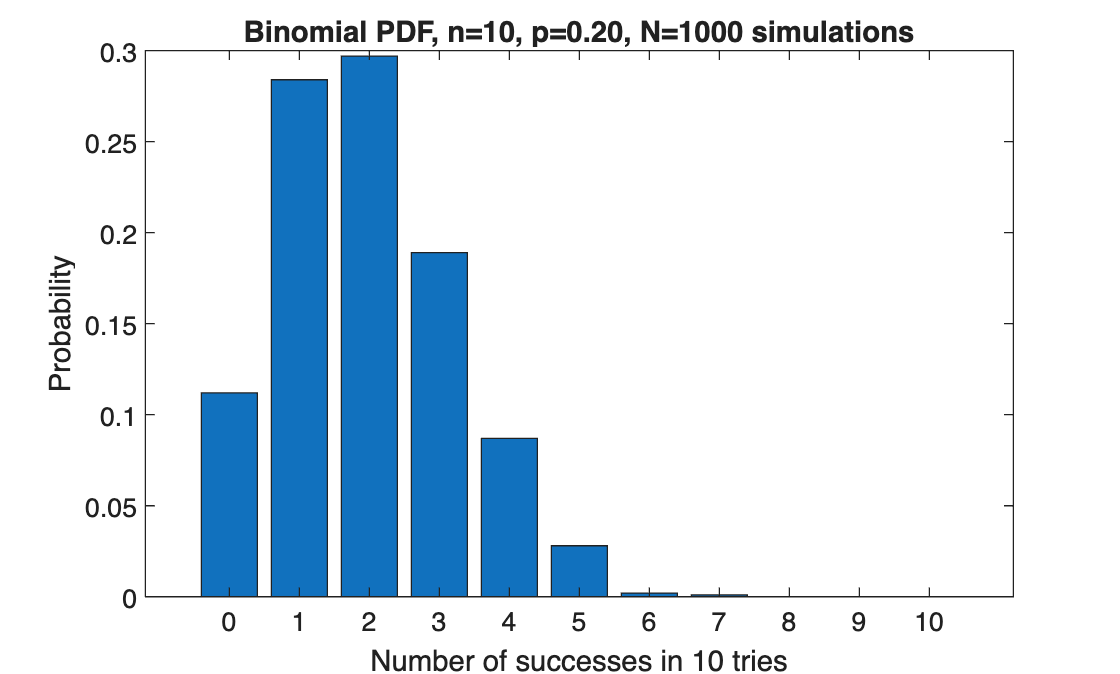

% Taken from the Binomial.m tutorial to represent probabilities of discrete
% quanta
p = 0.2;
n = 10;                    % number of "trials" 
NumExperiments = 1000;     % number of "experiments"
N = NumExperiments;
outcomes = binornd(n,p,NumExperiments,1);

% Make histogram of all possible outcomes. We want bins centered on whole
% numbers so we offset the edges
edges = -0.5:10.5;
counts = histcounts(outcomes, edges);
xs = edges(1:end-1)+diff(edges)/2;

% Normalize it to make it a pdf. Here counts (the x-axis of the histogram)
% is a DISCRETE variable, so we just have to add up the values
countProb = counts./sum(counts); 
bar(xs, countProb);
title(sprintf('Binomial PDF, n=%d, p=%.2f, N=%d simulations', ...
   n,p,N));
xlabel(sprintf('Number of successes in %d tries', n));
ylabel('Probability');


% Display probabilities in table format for ease of view
ProbabilityTable = table((0:10)', countProb', 'VariableNames',["Quanta", "Probability"]);
disp(ProbabilityTable)

    Quanta    Probability
    ______    ___________

       0         0.112   
       1         0.284   
       2         0.297   
       3         0.189   
       4         0.087   
       5         0.028   
       6         0.002   
       7         0.001   
       8             0   
       9             0   
      10             0   



## Exercise 2

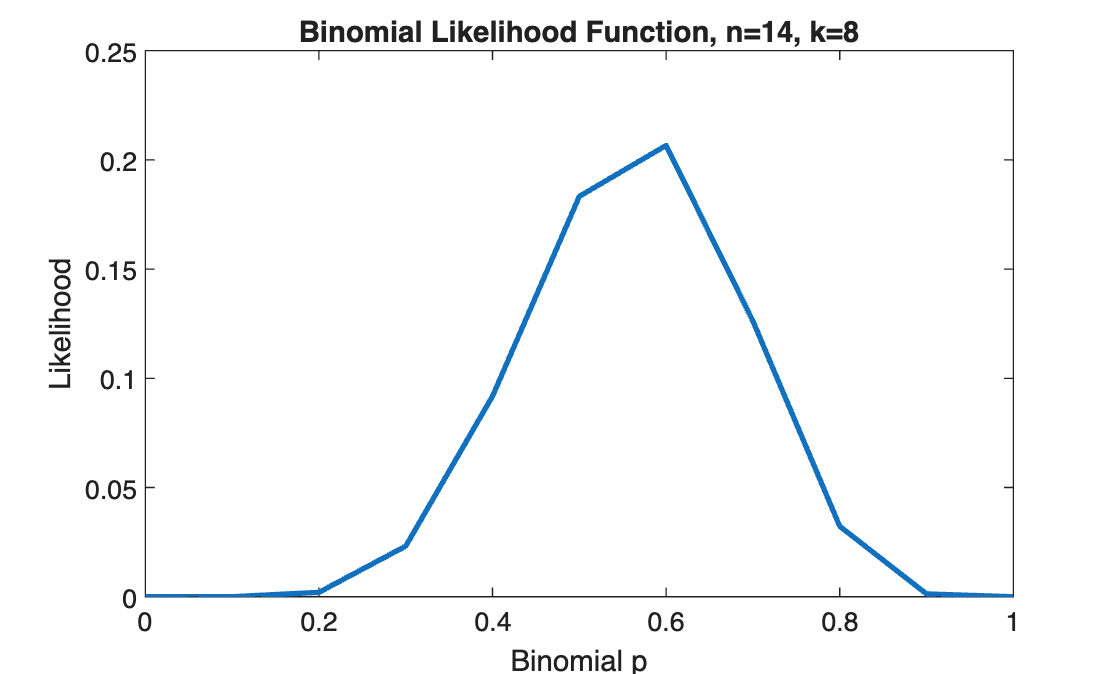

% Establish the baseline parameters used in the problem 
n = 14; 
k = 8; 
trueP = 0.0:0.1:1.0; 
releaseP = ones(1,length(trueP));

for i=1:length(trueP)
    releaseP(i) = nchoosek(n, k) * trueP(i)^k * (1-trueP(i))^(n-k);
end

% Plot a graph of the binomial likelihood function
plot(trueP, releaseP, 'LineWidth', 2)
title(sprintf('Binomial Likelihood Function, n=%d, k=%d', ...
   n,k));
xlabel(sprintf('Binomial p'));
ylabel('Likelihood');


% Locate the release probabilities asked in the question as well as the max
% probability 
index1 = find(trueP == 0.1);
index2 = find(trueP == 0.7);
[~, maxReleaseP] = max(releaseP);
maxTrueP = trueP(maxReleaseP);

% Display collected values
disp(['True Probability = 0.1, Release Probability = ', num2str(releaseP(index1))]);

True Probability = 0.1, Release Probability = 1.5959e-05


disp(['True Probability = 0.7, Release Probability = ', num2str(releaseP(index2))]);

True Probability = 0.7, Release Probability = 0.1262


disp(['Most probable release value is ', num2str(maxTrueP)]);

Most probable release value is 0.6


## Exercise 3

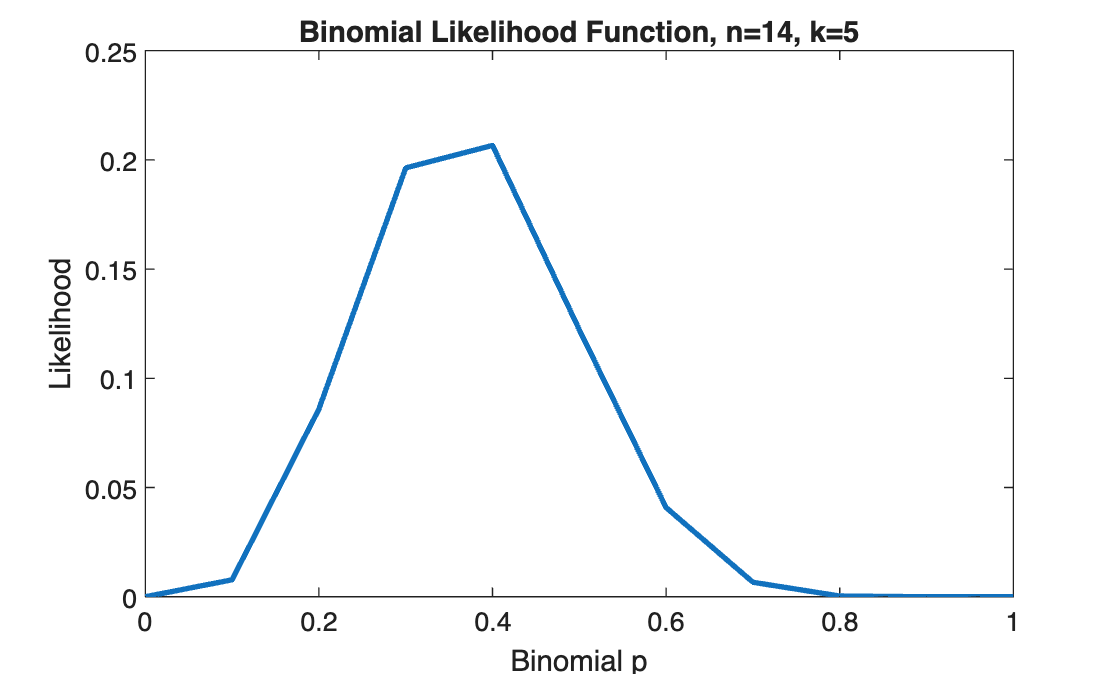

% Establish the baseline parameters used in the problem 
n = 14; 
k = 5; 
trueP = 0.0:0.1:1.0; 
releaseP2 = ones(1,length(trueP));

for i=1:length(trueP)
    releaseP2(i) = nchoosek(n, k) * trueP(i)^k * (1-trueP(i))^(n-k);
end

% Plot a graph of the binomial likelihood function
plot(trueP, releaseP2, 'LineWidth', 2)
title(sprintf('Binomial Likelihood Function, n=%d, k=%d', ...
   n,k));
xlabel(sprintf('Binomial p'));
ylabel('Likelihood');


% Locate the release probabilities asked in the question as well as the
% previous question and multiply the likelihoods or add the log-likelihoods
index1 = find(trueP == 0.1);
totalLikelihood = releaseP(index1) * releaseP2(index1);
totalLogLikelihood = log(releaseP(index1)) + log(releaseP2(index1));

% Display collected values
disp(['Total likelihood when true probability = 0.1: ', num2str(totalLikelihood)]);

Total likelihood when true probability = 0.1: 1.2378e-07


disp(['Total log-likelihood when true probability = 0.1: ', num2str(totalLogLikelihood)]);

Total log-likelihood when true probability = 0.1: -15.9047


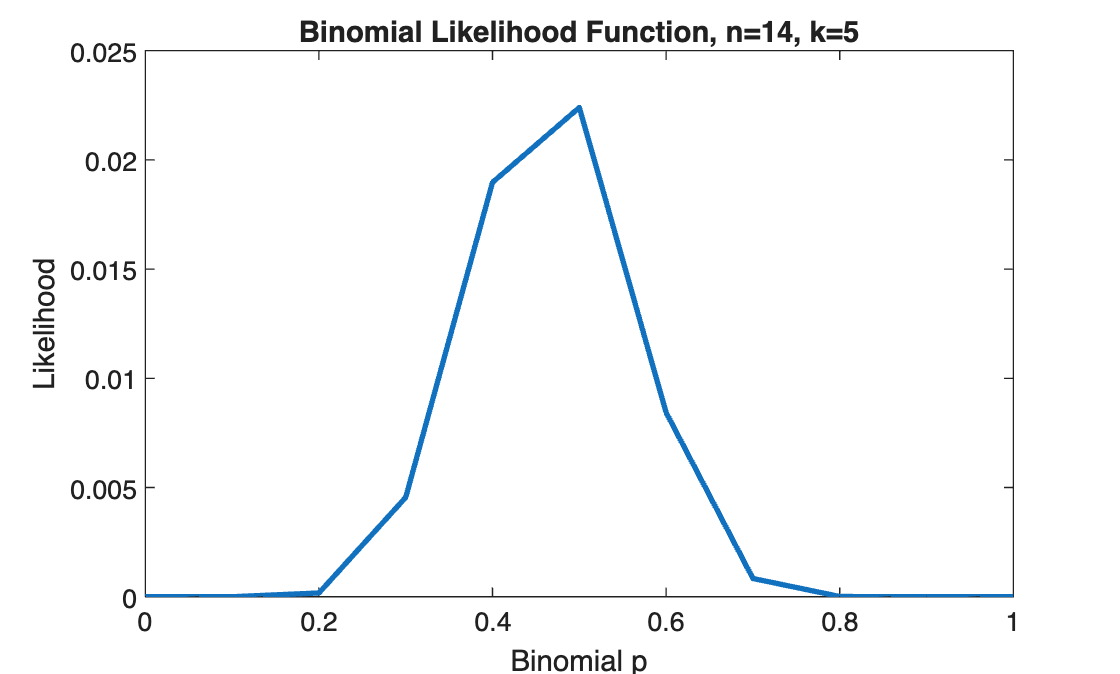


fullLikelihood = releaseP .* releaseP2;
fullLogLikelihood = log(releaseP) + log(releaseP2);

% Plot a graph of the binomial likelihood function
plot(trueP, fullLikelihood, 'LineWidth', 2)
title(sprintf('Binomial Likelihood Function, n=%d, k=%d', ...
   n,k));
xlabel(sprintf('Binomial p'));
ylabel('Likelihood');

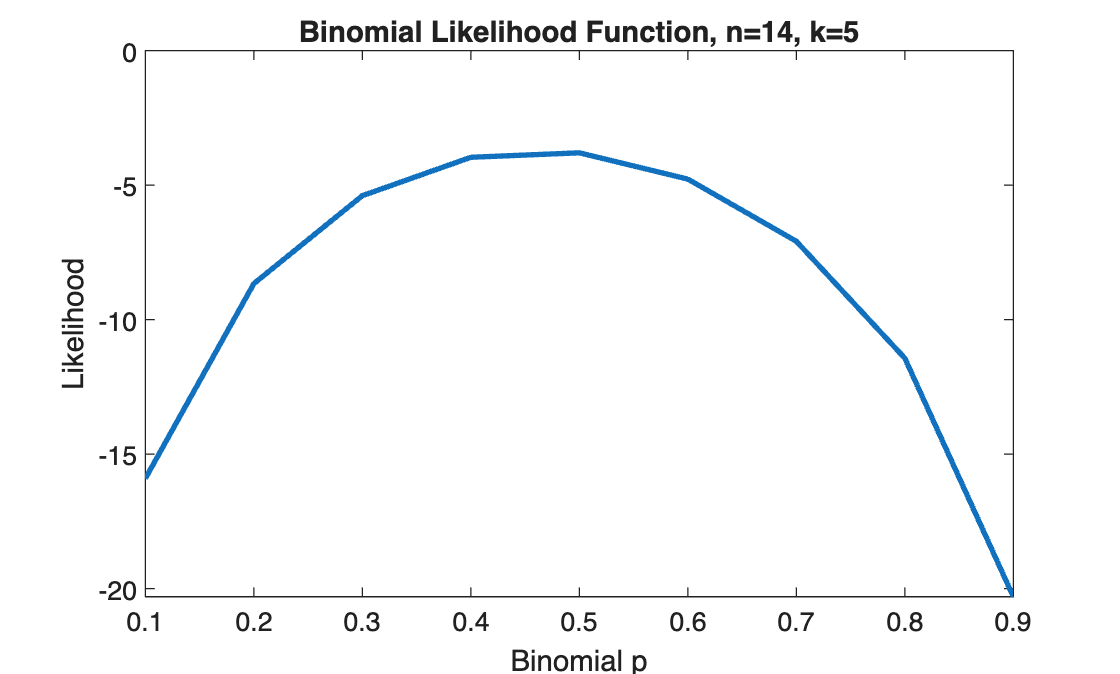


% Plot a graph of the binomial likelihood function
plot(trueP, fullLogLikelihood, 'LineWidth', 2)
title(sprintf('Binomial Likelihood Function, n=%d, k=%d', ...
   n,k));
xlabel(sprintf('Binomial p'));
ylabel('Likelihood');


[~, maxFullLikelihood] = max(fullLikelihood);
maxTrueP = trueP(maxFullLikelihood);
disp([sprintf('Most probable release value is %0.1f with a probability of %0.4f', ...
    maxTrueP, max(fullLikelihood))]);

Most probable release value is 0.5 with a probability of 0.0224


### Written Answers: 

Computing the function at higher resolutions allows for smoother distributions with more precise determination of likelihood trends (sample at 0.01 instead of 0.1). Additionally, the addition of another trial allows for a stronger likelihood peak overall at the region of maximal overlap with reduced likelihoods on the outer tails. 

## Exercise 4

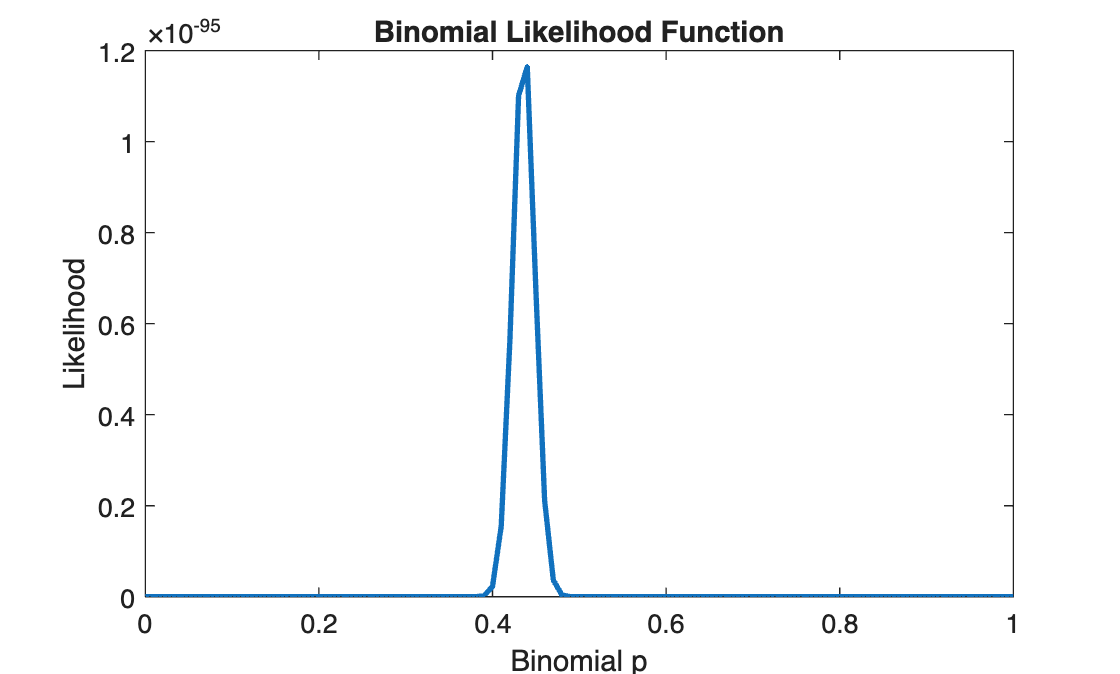

% Establish the baseline parameters used in the problem 
n = 14; 
k = [];
trueP = 0.0:0.01:1.0; 

% Store the measured releases as provided by the problem 
counts = [0 0 3 7 10 19 26 16 16 5 5 0 0 0 0];
for i = 1:length(counts)
    k = [k (i-1)*ones(1,counts(i))];
end

releaseP3 = ones(1,length(trueP));
fullReleaseP3 = ones(length(k), length(trueP));

for j=1:length(k)
    for i=1:length(trueP)
        releaseP3(i) = nchoosek(n, k(j)) * trueP(i)^k(j) * (1-trueP(i))^(n-k(j));
    end
    fullReleaseP3(j,:) = releaseP3;
end

fullLikelihood2 = prod(fullReleaseP3,1);
% Plot a graph of the binomial likelihood function
plot(trueP, fullLikelihood2, 'LineWidth', 2)
title(sprintf('Binomial Likelihood Function'));
xlabel(sprintf('Binomial p'));
ylabel('Likelihood');


[~, location] = max(fullLikelihood2);
phat = trueP(location);
disp([sprintf('The phat value that maximizes the likelihood based on these experiments is %0.4f', ...
    phat)]);

The phat value that maximizes the likelihood based on these experiments is 0.4400


## Exercise 5

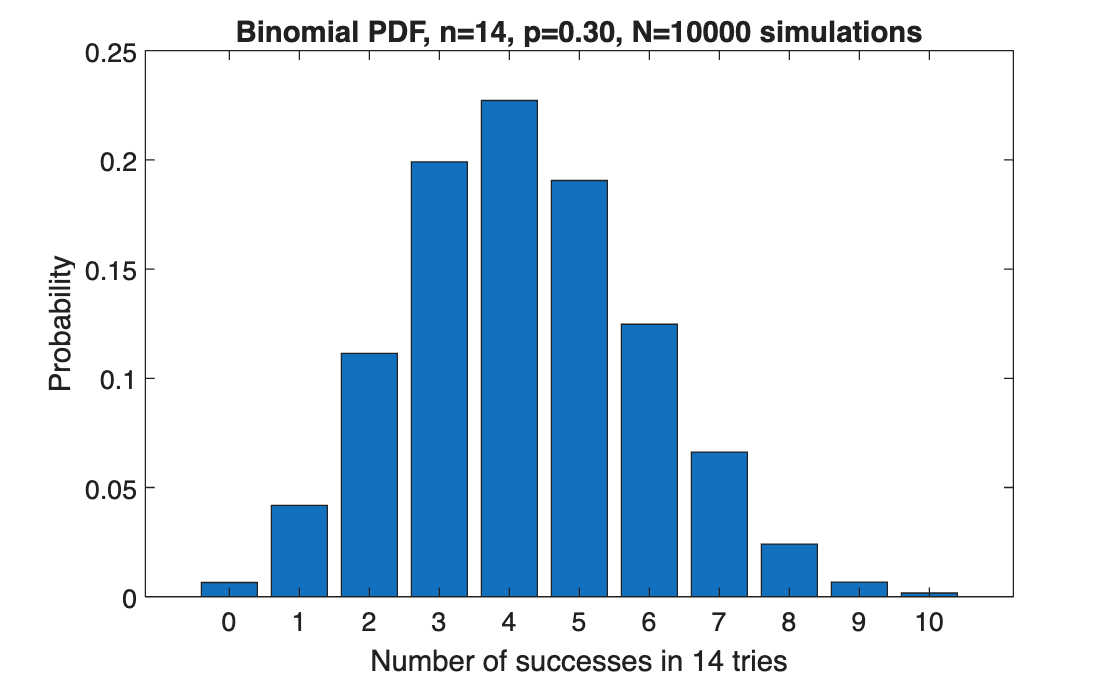

% Taken from the Binomial.m tutorial to represent probabilities of discrete
% quanta
p = 0.3;
n = 14;                    % number of "trials" 
NumExperiments = 1000;     % number of "experiments"
N = NumExperiments;
outcomes = binornd(n,p,NumExperiments,1);

% Make histogram of all possible outcomes. We want bins centered on whole
% numbers so we offset the edges
edges = -0.5:10.5;
counts = histcounts(outcomes, edges);
xs = edges(1:end-1)+diff(edges)/2;

% Normalize it to make it a pdf. Here counts (the x-axis of the histogram)
% is a DISCRETE variable, so we just have to add up the values
countProb = counts./sum(counts); 
bar(xs, countProb);
title(sprintf('Binomial PDF, n=%d, p=%.2f, N=%d simulations', ...
   n,p,N));
xlabel(sprintf('Number of successes in %d tries', n));
ylabel('Probability');

### Written Answers

The p-hat value coinciding with the maximum likelihood value still approximates 0.3 even in the setting of a changed temperature. As shown by the plot to the right, the probability of having 7 quanta released even with a true release probability of 0.3 (accepting the null) is appreciable at 0.059. This suggests the researchers are unable to meaningfully conclude that temperature had an effect in this scenario. 

## Bonus Exercise